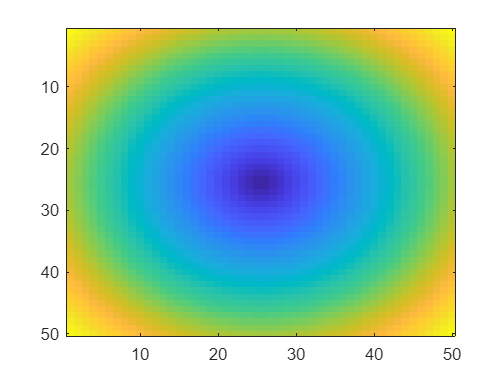

radius = 25;
k = find_circle(radius);

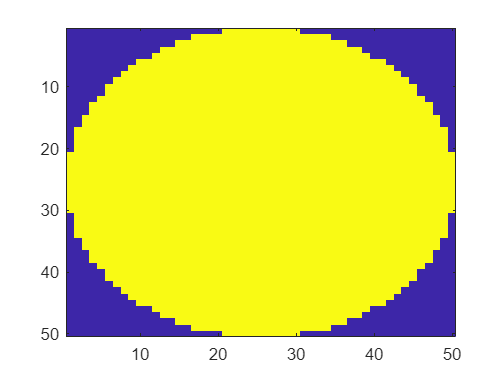

% FiberImage = 1:1264;
radii = radius * 2;
Image = zeros(radii);
% Image(k) = FiberImage;
Image(k) = 1;
imagesc(Image);

function k = find_circle(L)
R = zeros(2*L);
for i = 1:2*L
    for j = 1:2*L
        R(i,j) = sqrt((L-i+0.5)^2+(j-L-0.5)^2);
    end
end
imagesc(R);
k = find(R<L);
end